Transforming the data

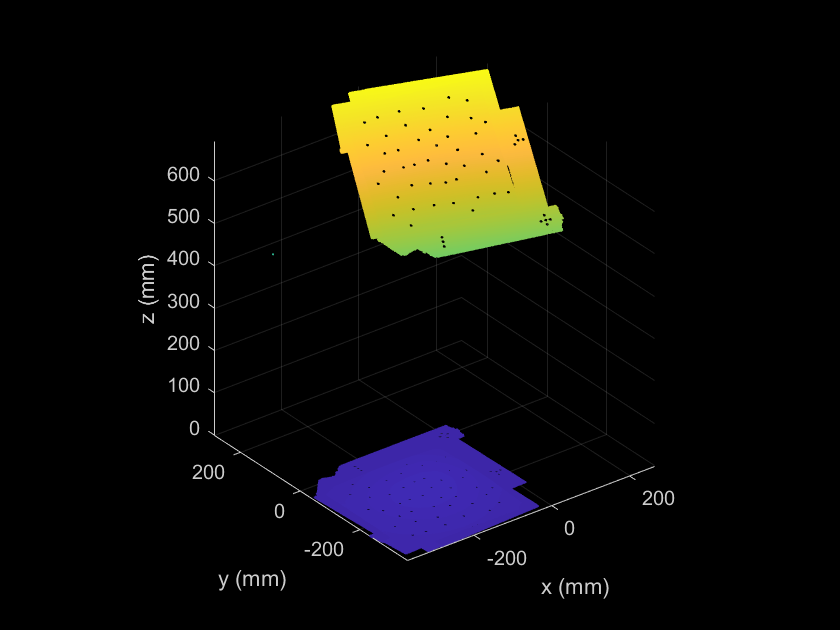

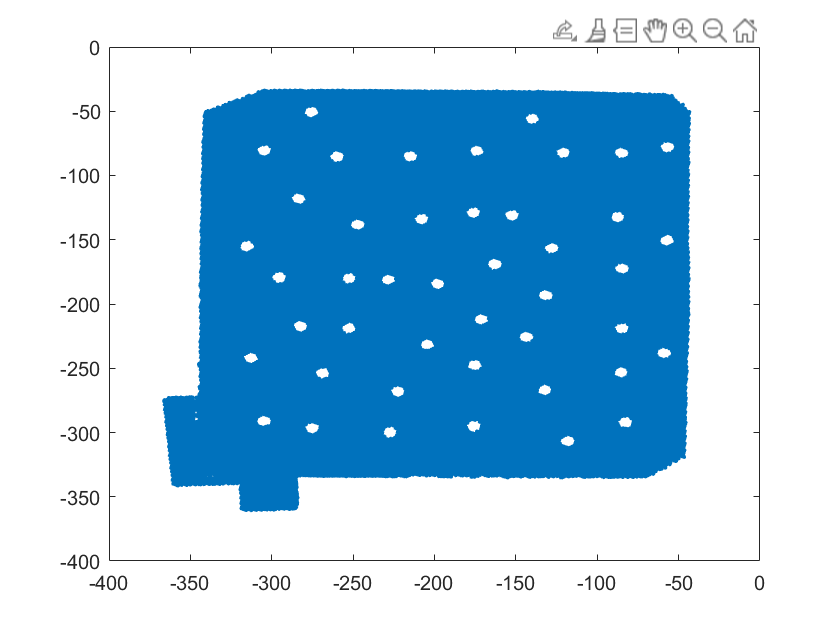

% Orientate data
G_model = PreProcess('markers_trial.p3','ptcloud.asc');

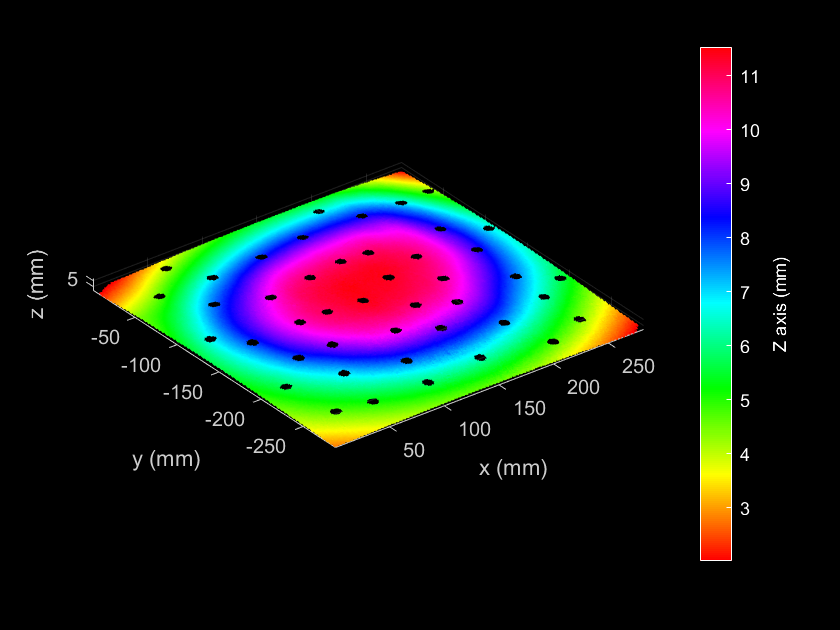

G_model.PtCloudShow()

Discretising the surface

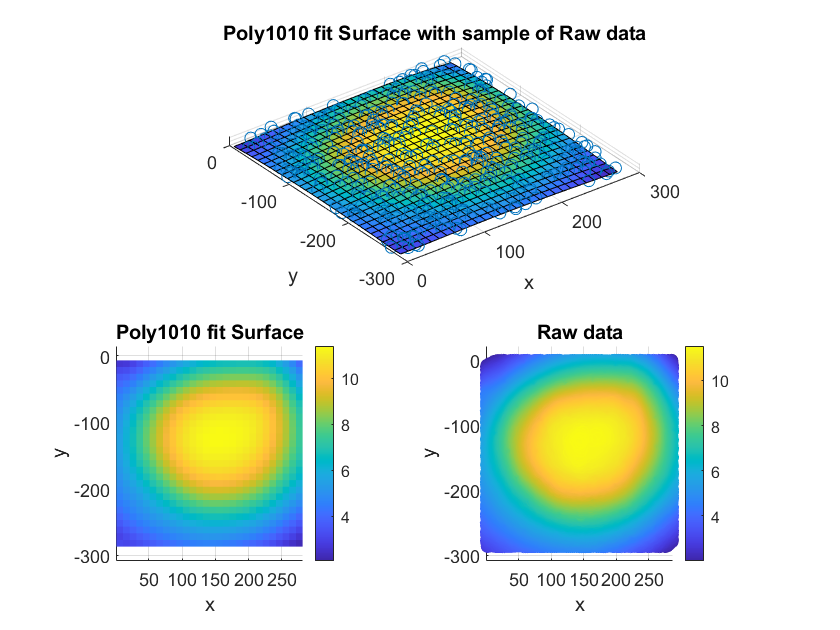

% Polynomial surface
poly_model = G_model.Poly(10,10);
poly_model.PolyShow()

% Explore error and resolution with increasing order
orders = [2, 3, 4, 5, 6, 7, 8, 9, 10, 12, 14];
res = [20, 10, 5, 1, 0.5];

error = zeros(length(orders),length(res));
time = zeros(length(orders),length(res));
for i = 1:length(orders)
    for j = 1:length(res)
        tStart = tic;
        poly_model = G_model.Poly(orders(i),res(j)).polymodel;
        error(i,j) = poly_model.RMSE;
        time(i,j) = toc(tStart);
        append('res: ',num2str(res(j)))
    end
    append('order: ',num2str(orders(i)))
end

ans = 'res: 20'

ans = 'res: 10'

ans = 'res: 5'

ans = 'res: 1'

ans = 'res: 0.5'

ans = 'order: 2'

ans = 'res: 20'

ans = 'res: 10'

ans = 'res: 5'

ans = 'res: 1'

ans = 'res: 0.5'

ans = 'order: 3'

ans = 'res: 20'

ans = 'res: 10'

ans = 'res: 5'

ans = 'res: 1'

ans = 'res: 0.5'

ans = 'order: 4'

ans = 'res: 20'

ans = 'res: 10'

ans = 'res: 5'

ans = 'res: 1'

ans = 'res: 0.5'

ans = 'order: 5'

ans = 'res: 20'

ans = 'res: 10'

ans = 'res: 5'

ans = 'res: 1'

ans = 'res: 0.5'

ans = 'order: 6'

ans = 'res: 20'

ans = 'res: 10'

ans = 'res: 5'

ans = 'res: 1'

ans = 'res: 0.5'

ans = 'order: 7'

ans = 'res: 20'

ans = 'res: 10'

ans = 'res: 5'

ans = 'res: 1'

ans = 'res: 0.5'

ans = 'order: 8'

ans = 'res: 20'

ans = 'res: 10'

ans = 'res: 5'

ans = 'res: 1'

ans = 'res: 0.5'

ans = 'order: 9'

ans = 'res: 20'

ans = 'res: 10'

ans = 'res: 5'

ans = 'res: 1'

ans = 'res: 0.5'

ans = 'order: 10'

ans = 'res: 20'

ans = 'res: 10'

ans = 'res: 5'

ans = 'res: 1'

ans = 'res: 0.5'

ans = 'order: 12'

ans = 'res: 20'

ans = 'res: 10'

ans = 'res: 5'

ans = 'res: 1'

ans = 'res: 0.5'

ans = 'order: 14'

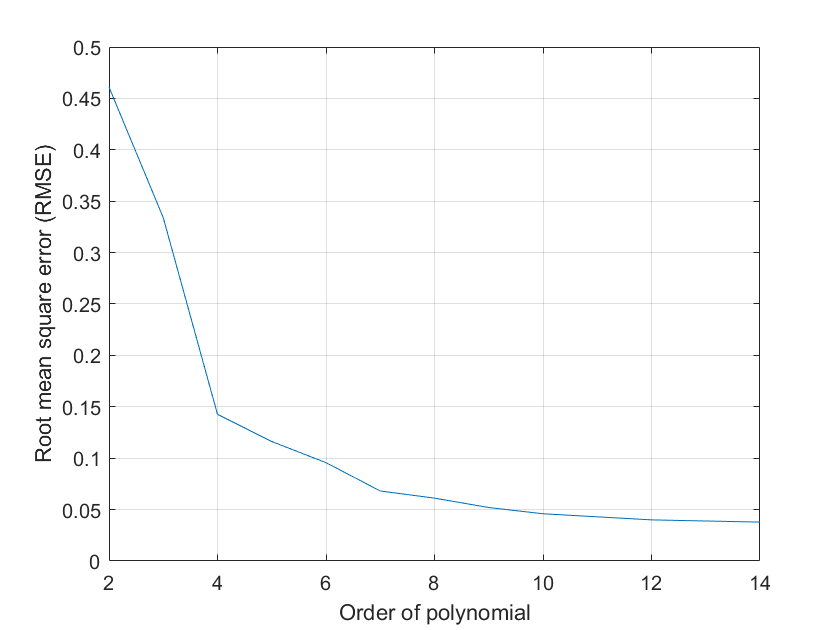

figure()
plot(orders,error(:,1))
xlabel('Order of polynomial')
ylabel('Root mean square error (RMSE)')
grid on

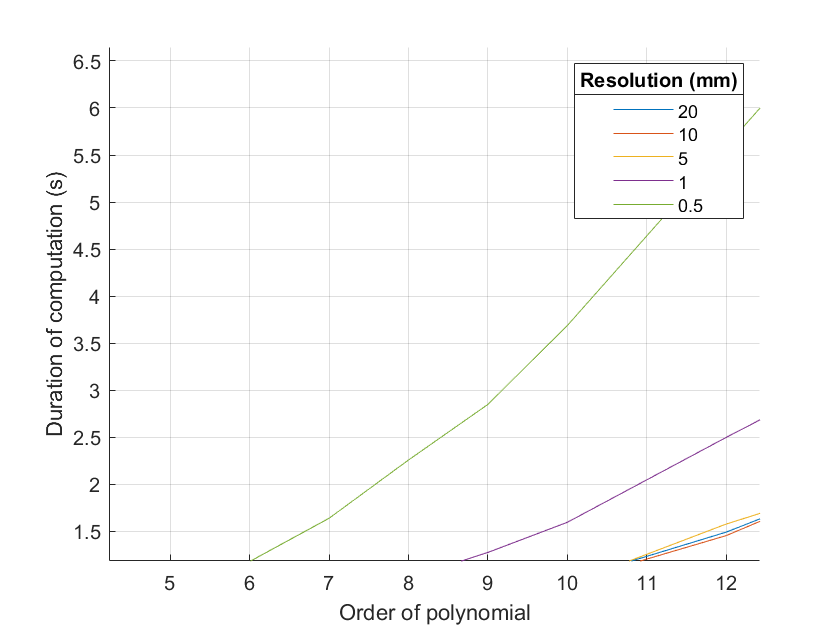


resolutions = {'20','10','5','1','0.5'};

figure()
hold on
for i = 1:length(time(1,:))
    plot(orders,time(:,i))
end
lgd = legend(resolutions);
title(lgd,sprintf('Resolution (mm)'),'FontSize',10)
xlabel('Order of polynomial')
ylabel('Duration of computation (s)')
%title('Computational efficiency with modelling surface using polynomial approximation')
grid on

res = [20,50,100,200,400,800,1500,100000];
time = zeros(length(res),1);
for i = 1:length(res) 
    tStart = tic;
    poly_model = G_model.Poly(10,res(i)).polymodel;
    time(i) = toc(tStart);
    append('res: ',num2str(res(i)))
end

ans = 'res: 20'

ans = 'res: 50'

ans = 'res: 100'

ans = 'res: 200'

ans = 'res: 400'

ans = 'res: 800'

ans = 'res: 1500'

ans = 'res: 100000'

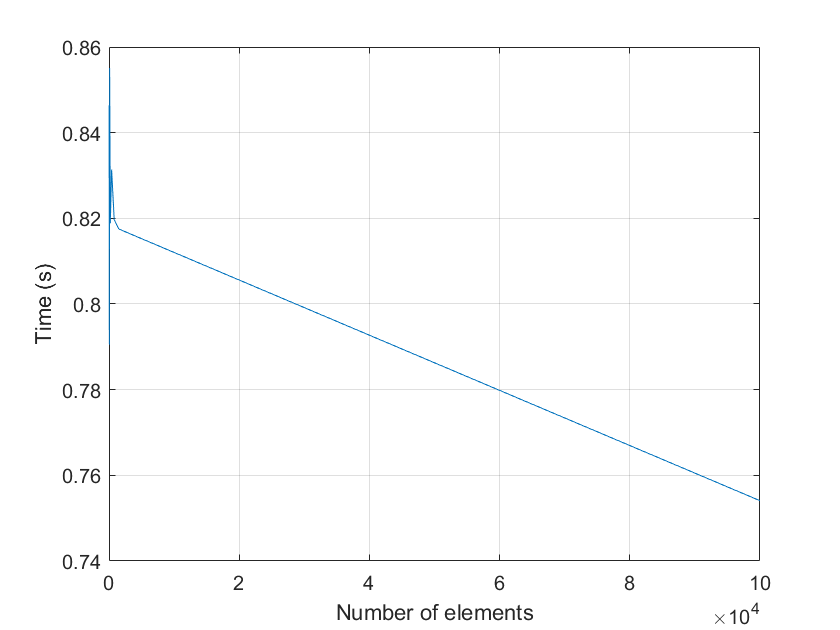

figure()
plot(res,time)
xlabel('Number of elements')
ylabel('Time (s)')
grid on

% Explore error with increasing resolution
resolution = [5,10,20,30,40,50];

error = zeros(length(orders),1);
time = zeros(length(orders),1);
for i = 1:length(orders)
    tStart = tic;
    poly_model = G_model.Poly(10,10).polymodel;
    error(i) = poly_model.RMSE;
    time(i) = toc(tStart);
    append('order: ',num2str(orders(i)))
end

poly_model = G_model.Poly(12,5)

poly_model =   PreProcess with properties:

       TCloud: [61777×3 double]
     polydata: {[58×57 double]  [58×57 double]  [58×57 double]}
    polymodel: [1×1 struct]
        Gauss: []
         Mean: []
         Pmax: []
         Pmin: []
          mag: 12
          inc: 5


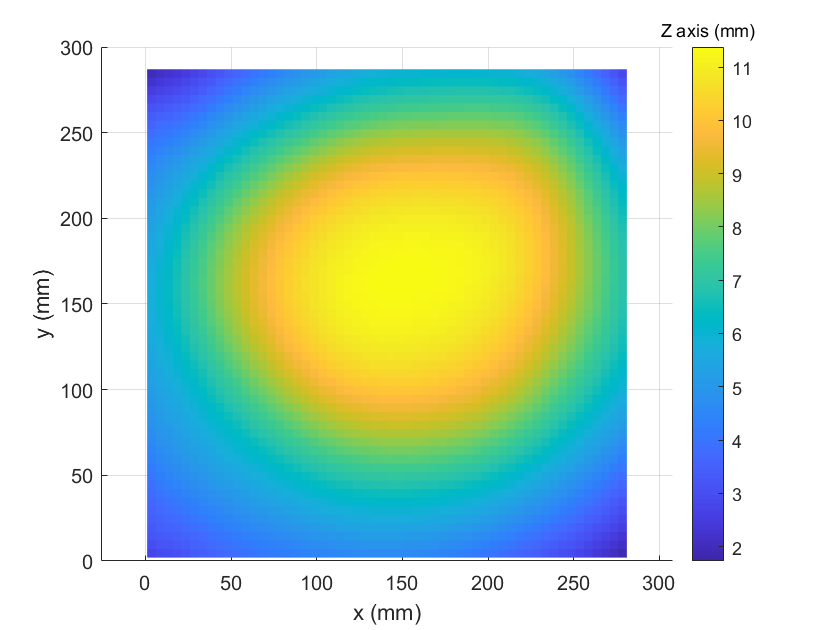

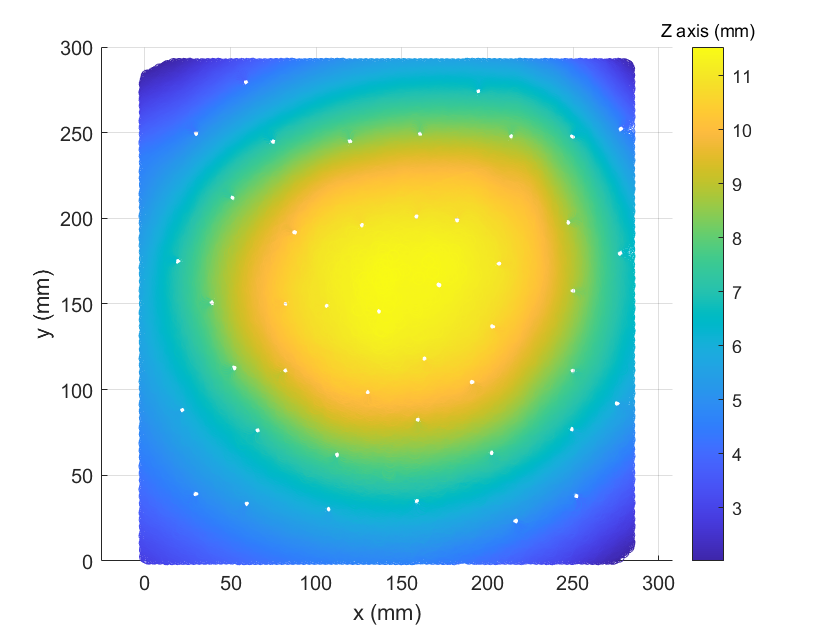

poly_model.PolyShow()

Representing the geometry

% Curvature
curve_model = poly_model.Curvature();
fig1 = figure

fig1 =   Figure (72) with properties:

      Number: 72
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [360 198 560 420]
       Units: 'pixels'

  Show all properties


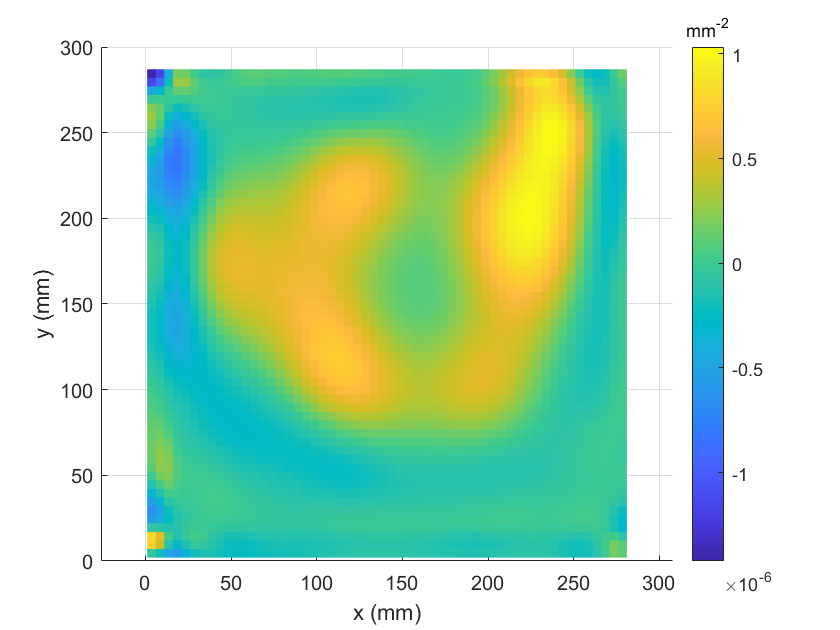

curve_model.ShowCurvature('Gauss')
hcb = colorbar;
hcb.Title.String = "mm^{-2}";
saveas(fig1, '..\Images\Post processing\gaussian_curvature.jpg')


fig1 = figure

fig1 =   Figure (73) with properties:

      Number: 73
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [360 198 560 420]
       Units: 'pixels'

  Show all properties


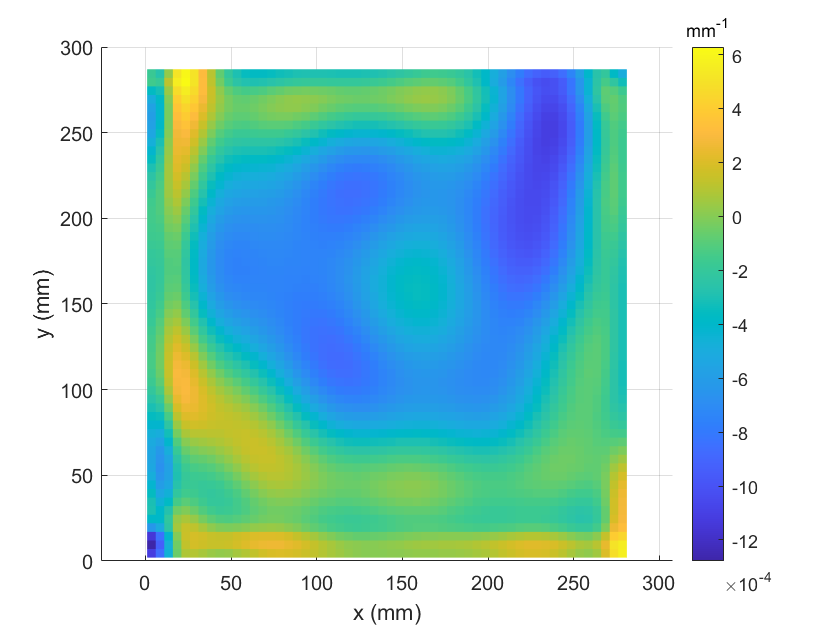

curve_model.ShowCurvature('Mean')
hcb = colorbar;
hcb.Title.String = "mm^{-1}";
saveas(fig1, '..\Images\Post processing\mean_curvature.jpg')


fig1 = figure

fig1 =   Figure (74) with properties:

      Number: 74
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [360 198 560 420]
       Units: 'pixels'

  Show all properties


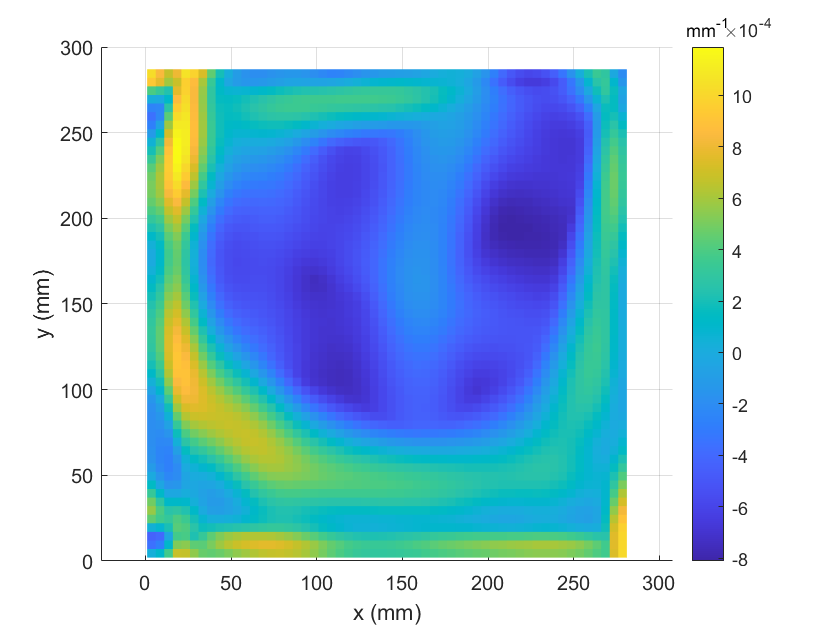

curve_model.ShowCurvature('P1')
hcb = colorbar;
hcb.Title.String = "mm^{-1}";
saveas(fig1, '..\Images\Post processing\principle1_curvature.jpg')


fig1 = figure

fig1 =   Figure (75) with properties:

      Number: 75
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [360 198 560 420]
       Units: 'pixels'

  Show all properties


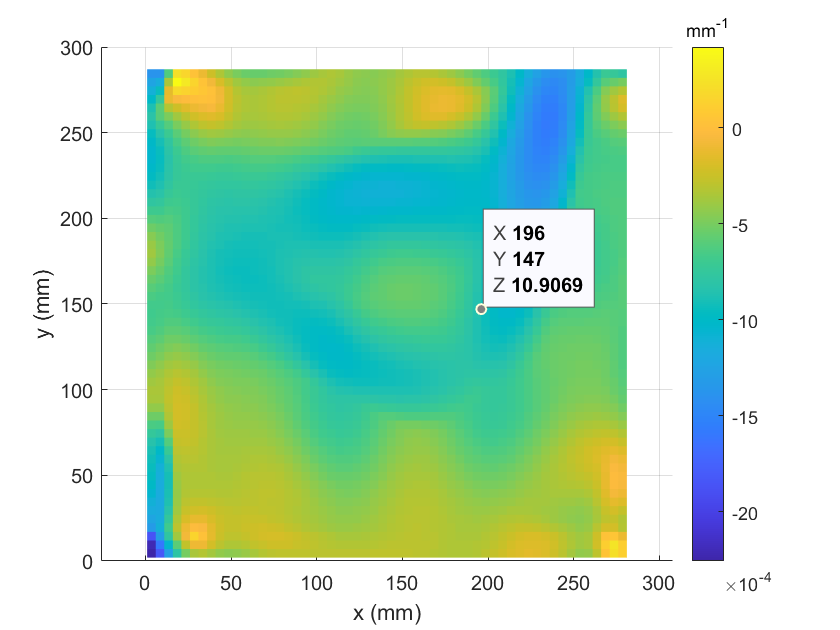

curve_model.ShowCurvature('P2')
hcb = colorbar;
hcb.Title.String = "mm^{-1}";
saveas(fig1, '..\Images\Post processing\principle2_curvature.jpg')

Automate generation and saving of entire dataset

% Get directory
path = uigetdir()

% Get marker files
mfilelist = dir(append(path,'\markers'));

% Get point cloud files
pfilelist = dir(append(path,'\point_clouds'));

for i = 1:length(mfilelist)
    
    name = mfilelist{i}(1:end-3);
    
    % Process data
    G_model = PreProcess(mfilelist(i),pfilelist(i));
    poly_model = G_model.Poly(12,10);
    curve_model = poly_model.Curvature();
    
    % Save raw data
    G_model.SaveRaw(append(path,'\Raw'),name)
    
    % Save polynomial data
    poly_model.SavePolyAsMat(append(path,'\PolyMat'),name);
    
    if mod(i,5) == 0
        poly_model.SavePolyAsImg(append(path,'\PolyImg\test'),name);
    else
        poly_model.SavePolyAsImg(append(path,'\PolyImg\train'),name);
    end
    
    types = {'Gauss','Mean','Pmax','Pmin'};
    
    % Save curve data
    for j = 1:4
        curve_model.SaveCurvAsMat(append(path,'\CurveMat'),append(name,'_',types{j}),types{j});
        if mod(i,5) == 0
            curve_model.SaveCurvAsImg(append(path,'\CurveImg\test'),append(name,'_',types{j}),types{j});
        else
            curve_model.SaveCurvAsImg(append(path,'\CurveImg\train'),append(name,'_',types{j}),types{j});
        end
    end
end